r=pi;

#### Simulazione e plot

mkdir ('Risultati FeedBack')

standard_model = 'FBL_WP4_sim.slx';
open_system(standard_model);
data = sim(standard_model, 10);

Found algebraic loop containing: 
FBL_WP4_sim/Interpreted MATLAB Function3
FBL_WP4_sim/Interpreted MATLAB Function2
FBL_WP4_sim/Interpreted MATLAB Function (algebraic variable)


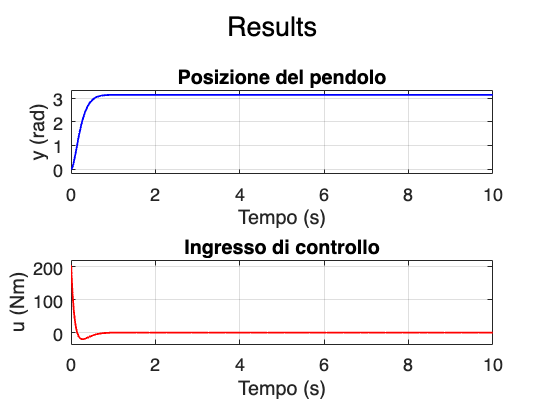

plot_data(data,"FBL_WP4_sim")
saveas(gcf, 'Risultati FeedBack/Results.png');

#### Analisi

results=stepinfo(data.y.Data,data.t.Data);
disp('Step Information for the Output');

Step Information for the Output


disp(results); 

         RiseTime: 0.3870
    TransientTime: 0.6525
     SettlingTime: 0.6525
      SettlingMin: 2.8770
      SettlingMax: 3.1418
        Overshoot: 0.0069
       Undershoot: 0
             Peak: 3.1418
         PeakTime: 1.2229

